%% Plotting dose-responde for endpoint-gender
close all
clear all
clc

%% Data Import
opts=detectImportOptions('../data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
data=readtable('../data/MiniProjectEFSA.xlsx', opts);
data.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

dose=[0, 30, 100, 150];

data_male_1 = data(data.endpoint==1&data.sex==0,:);
data_female_1 = data(data.endpoint==1&data.sex==1,:);
data_male_2 = data(data.endpoint==2&data.sex==0,:);
data_female_2 = data(data.endpoint==2&data.sex==1,:);
data_male_3 = data(data.endpoint==3&data.sex==0,:);
data_female_3 = data(data.endpoint==3&data.sex==1,:);

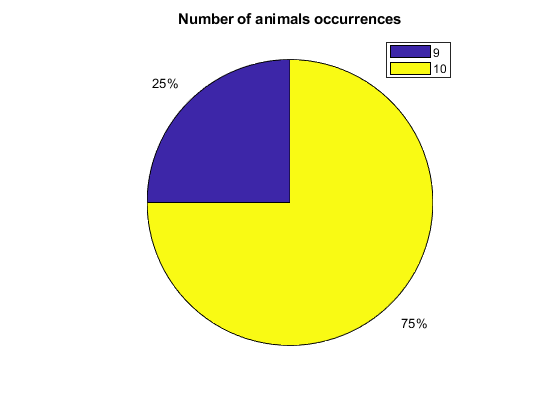

figure
pie(groupcounts(data.numberOfAnimals),"%.f%%")
title('Number of animals occurrences')
legend("9","10")

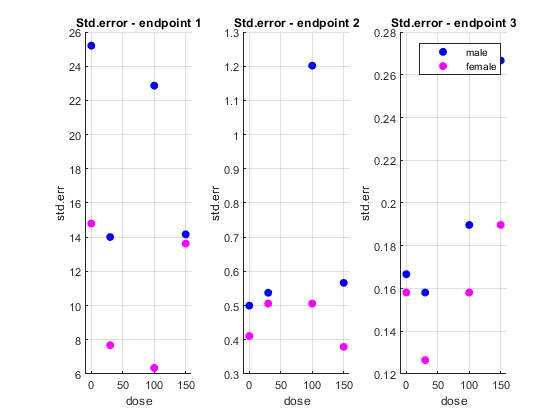

figure
subplot(1,3,1)
scatter(dose,data_male_1.SD./sqrt(data_male_1.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,data_female_1.SD./sqrt(data_female_1.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 1")
xlabel("dose")
ylabel("std.err")

subplot(1,3,2)
scatter(dose,data_male_2.SD./sqrt(data_male_2.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,data_female_2.SD./sqrt(data_female_2.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 2")
xlabel("dose")
ylabel("std.err")

subplot(1,3,3)
scatter(dose,data_male_3.SD./sqrt(data_male_3.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,data_female_3.SD./sqrt(data_female_3.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 3")
xlabel("dose")
ylabel("std.err")
legend("male","female")

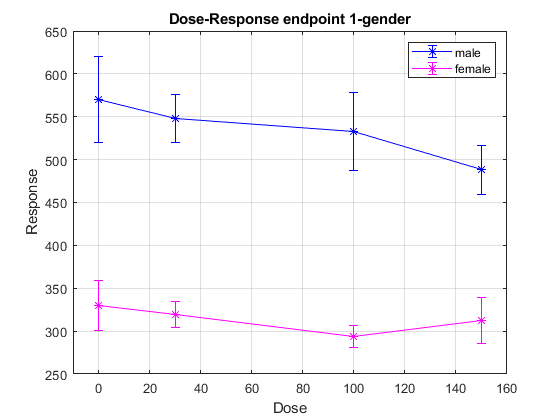

%Endpoint 1
figure
errorbar(dose,data_male_1.response,2*(data_male_1.SD./sqrt(data_male_1.numberOfAnimals)),"-*b")
xlim([-10 160])
grid on
hold on
errorbar(dose,data_female_1.response,2*(data_female_1.SD./sqrt(data_female_1.numberOfAnimals)),"-*m")
title('Dose-Response endpoint 1-gender')
xlabel('Dose')
ylabel('Response')
legend("male","female")

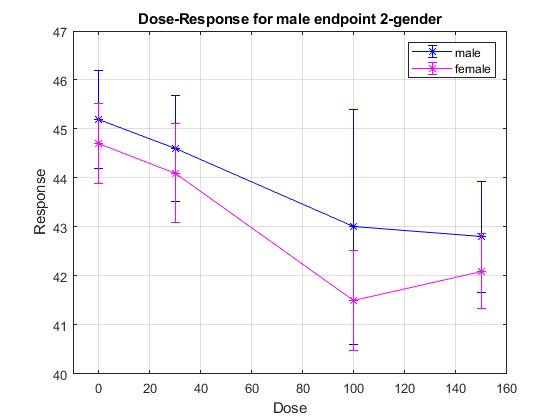

%Endpoint 2 
figure
errorbar(dose,data_male_2.response,2*(data_male_2.SD./sqrt(data_male_2.numberOfAnimals)),"-*b")
grid on
hold on
errorbar(dose,data_female_2.response,2*(data_female_2.SD./sqrt(data_female_2.numberOfAnimals)),"-*m")
xlim([-10 160])
title('Dose-Response for male endpoint 2-gender')
xlabel('Dose')
ylabel('Response')
legend("male","female")

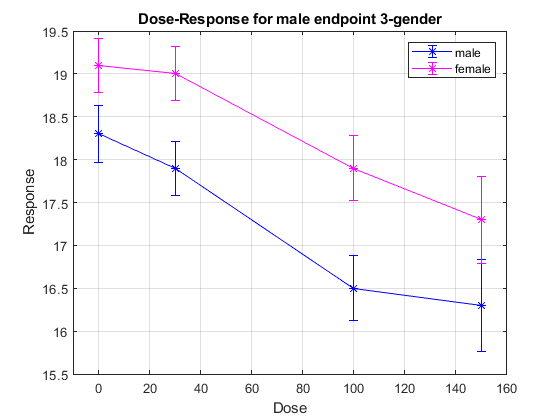

%Endpoint 3
figure
errorbar(dose,data_male_3.response,2*(data_male_3.SD./sqrt(data_male_3.numberOfAnimals)),"-*b")
grid on
hold on
errorbar(dose,data_female_3.response,2*(data_male_3.SD./sqrt(data_female_3.numberOfAnimals)),"-*m")
xlim([-10 160])
title('Dose-Response for male endpoint 3-gender')
xlabel('Dose')
ylabel('Response')
legend("male","female")

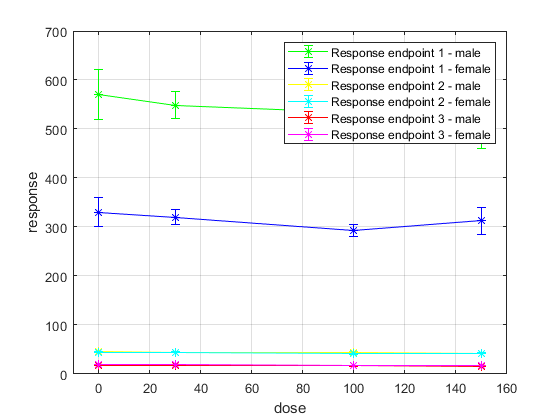

figure
errorbar(dose,data_male_1.response,2*(data_male_1.SD./sqrt(data_male_1.numberOfAnimals)),"-*g")
hold on
errorbar(dose,data_female_1.response,2*(data_female_1.SD./sqrt(data_female_1.numberOfAnimals)),"-*b")
hold on
errorbar(dose,data_male_2.response,2*(data_male_2.SD./sqrt(data_male_2.numberOfAnimals)),"-*y")
hold on
errorbar(dose,data_female_2.response,2*(data_female_2.SD./sqrt(data_female_2.numberOfAnimals)),"-*c")
hold on
errorbar(dose,data_male_3.response,2*(data_male_3.SD./sqrt(data_male_3.numberOfAnimals)),"-*r")
hold on
errorbar(dose,data_female_3.response,2*(data_male_3.SD./sqrt(data_female_3.numberOfAnimals)),"-*m")
xlim([-10 160])
grid on
xlabel("dose")
ylabel("response")
legend("Response endpoint 1 - male","Response endpoint 1 - female","Response endpoint 2 - male","Response endpoint 2 - female",...
    "Response endpoint 3 - male","Response endpoint 3 - female");